# Tutorial example: 1D function

In this example, we apply PCE-GPR to a simple illustrative 1D function, i.e.,


$$y=\mathcal{M}(x)=e^{-10/x}(2\cos(x)+\sin(x))$$


We consider $x\sim\mathcal{U}(1,9)$ as the distribution of the input variable.

## Initialization

Cleaning and definition of plot parameters

% cleaning
clear all
clc
close all

% plot parameters
BLUE = [0 0.4470 0.7410];
RED = [0.8500 0.3250 0.0980];
YELLOW = [0.9290 0.6940 0.1250];
GREEN = [0.4660,0.6740,0.1880];
GRAY = [0.6,0.6,0.6];
PURPLE = [0.4940, 0.1840, 0.5560];
CYAN = [0.3010, 0.7450, 0.9330];

Define simulation parameters. You are allowed to:

- change the number of training samples `Ntrain` (affects the overall accuracy of the PCE-GPR model)

- choose between randomly-distributed or equally-spaced training samples

- change the PCE order `p` (affects the accuracy of the approximate PCE model vs the GPR model and the associated statistics)

- change the standard deviation of noise on the training observations (`sigma_n`)

- choose the hyperparameter estimation method: maximum likelihood (ML; toolbox default) or cross-validation (CV)

- chose between interpolation or regression mode (neglects or considers noise on the training observations)

- change the number of posterior sample trajectories `Ntraj` (affects the accuracy of numerical calcultions of posterior distributions)

- change the number `Nrho` of points in the hyperparameter sweep

% simulation parameters
d = 1; % number of random input parameters
Ntrain =9; % number of training samples
random_samples = false; % random or equally-spaced training samples
p =20; % maximum PCE order
sigma_n =0; % noise standard deviation
EstimationMethod = 'ML'; % hyperparameter estimation method
Noise = false; % interpolation or regression mode
Ntraj = 10000; % number of posterior trajectories (for numerical calculations)
Nmc = 1e3; % number of test Monte Carlo samples (for error estimates)
Nval = 201; % number of evaluation samples for plots
Nrho = 31; % number of values for hyperparameter sweep
nugget = 1e-10; % regularization term for posterior covariances

rng(1); % for reproducibility

% define target function
fun = @(x) exp(-10./x).*(2*cos(x)+sin(x));

% define input distribution
Xdist = makedist("Uniform","lower",1,"upper",9);


## Parametric plot

First of all, we draw a plot that displays the target function.

% define x-axis
x = linspace(Xdist.Lower,Xdist.Upper,Nval)';

% calculate function
y = fun(x);

% plot
figure(1)
plot(x,y,'-','linewidth',1,'color',BLUE,'DisplayName','actual function'); hold on;
xlabel('$x$','interpreter','latex');
ylabel('$y$','interpreter','latex');
title('Function approximation');
legend('Location','northwest');
set(gca,'xlim',[x(1),x(end)]);

## Training samples

Next, we compute training samples by either:

- taking them equally spaced between the lower and upper distribution bounds;

- drawing them randomly from the input distribution using Latin hypercube sampling (LHS)

according the selected option. The training samples are displayed as red dots in the plot.

if random_samples
    % draw random training points
    x_lhs = lhsdesign(Ntrain,d);
    x_train = Xdist.icdf(x_lhs);
else
    x_train = linspace(Xdist.Lower,Xdist.Upper,Ntrain)';
end

% compute training observations (+ noise)
y_train = fun(x_train) + sigma_n*randn(Ntrain,1);

% plot training samples
figure(1)
plot(x_train,y_train,'o','color',RED,'markerfacecolor',RED,'DisplayName','training samples');

## Training the PCE-GPR model

We now train our PCE-GPR model with the specified settings. Before calling the training function, we need to define the structure describing the input distribution.

% define distribution structure
distr.Type = 'unif';
distr.Parameters = [Xdist.Lower,Xdist.Upper];

% train PCE-GPR model
M_pce_gpr = train_pce_gpr(x_train,y_train,distr,'EstimationMethod',EstimationMethod,'Noise',Noise);

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\EMC Group\tools\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information

---   Calculating the Kriging metamodel...                              ---

                          Median        Current pop   Stall
Generation   f-count      f(x)          best f(x)     

## Evaluating the GPR model

We can now use the PCE-GPR model to make predictions at points $x$.

% PCE-GPR prediction
[y_pred_gpr,~,cov_pred_gpr] = predict_pce_gpr(M_pce_gpr,x);

The prediction `y_pred_gpr` is computed using the GPR (kernel) model, which reads


$$y=\sum_{l=1}^{N_\mathrm{train}}\alpha_lr(x,x_l)$$


The above calculation can be vectorized to obtain the vector with all predictions at specificied points as


$$\mathbf{y}=\mathbf{R}_*\mathbf{\alpha}$$


where $\mathbf{R}_*$ is a $N_\mathrm{val}\times N_\mathrm{train}$ matrix with entries


$$[\mathbf{R}_*]_{il}=r(x^*_i,x_l)$$


Note that, in the notation, we use the superscript * to distinguish evaluation points `x` from training points `x_train`.

Both the coefficients $\mathbf{\alpha}$ and the prior correlation or kernel function $r(x,x^\prime)$ are available in the PCE-GPR model structure as fields `.alpha` and `.kernel`, respectively. It is important to mention that the kernel function is defined in terms of the standardized distribution, $\mathcal{U}(-1,1)$ in this case. This is handled internally to PCE-GPR functions and transparently to the user, but the above standardization can be achived using the `standardize_input `function, if needed.

The variable `cov_pred_gpr` is the covariance matrix between model predictions. Its diagonal is the variance of local predictions and can be used to draw 95% confidence levels, which are displayed as a shaded green area.

The posterior covariance between two model predictions at points $x$ and $x^\prime$ is computed as


$$\varsigma^2(x,x^\prime)=\sigma_\mathrm{tot}^2\left(\tilde{r}(x,x^\prime)-\sum_{l,m=1}^{N_\mathrm{train}}\tilde{r}(x,x_l)\left[\tilde{\mathbf{R}}^{-1}\right]_{lm}\tilde{r}(x_m,x^\prime)\right)$$


In the above equations, the "tilde" variables are defined as


$$\tilde{r}(x,x^\prime)=(1-\tau)r(x,x^\prime)$$


and


$$\tilde{\mathbf{R}}=(1-\tau)\mathbf{R}+\tau\mathbf{I}$$


where $\mathbf{I}$ is the $N_\mathrm{train}\times N_\mathrm{train}$ identity matrix and $\mathbf{R}$ has entries


$$R_{lm}=r(x_l,x_m)$$


Moreover,


$$\tau=\frac{\sigma_n^2}{\sigma^2+\sigma_n^2}$$


is the noise ratio, whereas


$$\sigma_\mathrm{tot}^2=\sigma^2+\sigma_n^2$$


is the total variance (sum of kernel variance $\sigma^2$ and noise variance $\sigma_n^2$).

By introducing the Cholesky factorization $\tilde{\mathbf{R}}=\mathbf{L}\mathbf{L}^T$, the entire covariance matrix between all model predictions can be computed as


$$\mathbf{\Sigma}=\sigma_\mathrm{tot}^2\left(\tilde{\mathbf{R}}_{**}-\tilde{\mathbf{R}}_*^T(\mathbf{L}\mathbf{L}^T)^{-1}\tilde{\mathbf{R}}_*\right)=\sigma_\mathrm{tot}^2\left(\tilde{\mathbf{R}}_{**}-(\mathbf{L}^{-1}\tilde{\mathbf{R}}_*)^T(\mathbf{L}^{-1}\tilde{\mathbf{R}}_*)\right)$$


where


$$\tilde{\mathbf{R}}_{*}=(1-\tau)\mathbf{R}_*$$


and


$$[\tilde{\mathbf{R}}_{**}]_{ij}=(1-\tau)r(x^*_i,x^*_j)$$


The model structure provides the values of $\tau$, $\sigma$, and $\sigma_n$ in fields .`tau`, `.sigma`, and `.sigma_n`, respectively, and the Cholesky factor $\mathbf{L}$ in the field `.L`.

% confidence interval
sig2_pred_gpr = diag(cov_pred_gpr);
ci_pred_gpr(:,1) = y_pred_gpr - 2*sqrt(sig2_pred_gpr); % lower confidence bound
ci_pred_gpr(:,2) = y_pred_gpr + 2*sqrt(sig2_pred_gpr); % upper confidence bound

% plot
figure(1)
plot(x,y_pred_gpr,'--','LineWidth',1.5,'Color',GREEN,'DisplayName','GPR model');
hP = plot_bounds(x,ci_pred_gpr,GREEN,0.25);
set(hP,'DisplayName','95% CI');

## Posterior trajectories

Once we know the covariance matrix, we can also calculate posterior trajectories. The model predictions are a multivariate Gaussian random vector with mean vector `y_pred_gpr` and covariance matrix `cov_pred_gpr`. Here, we add 10 random trajectories to the plot. Note that if the interpolation mode is selected, the model does not assume noise on the training data that are therefore interpolated by predictions and trajectories. Note that a small "nugget" is added to the diagonal of the covariance matrix to improve conditioning and make sure the matrix is positive definite.

% random posterior trajectories
y_post = y_pred_gpr + sqrtm(cov_pred_gpr+nugget*eye(Nval))*randn(Nval,10);

% plot
figure(1)
hP = plot(x,y_post,'-','Color',GRAY,'LineWidth',1);
hP(1).DisplayName = 'posterior trajectories (GPR model)';
uistack(hP,"bottom");
for ii = 2:length(hP)
    hP(ii).Annotation.LegendInformation.IconDisplayStyle = 'off'; % display only one trajectory in the legend
end

## Polynomial chaos expansion model

As we have seen, the GPR part of the PCE-GPR model allows us to calculate predictions. However, we may want to convert this model into an approximate PCE with the predefined order `p`, from which statistical moments and sensitivity indices are computed analytically. To this end, we need to

- Compute the set of multi-indices using the function `PCEindex`

- Use the method `get_pce_gpr_coeff `to obtain the corresponding PCE coefficients.

The PCE coefficients are computed probabilistically in terms of an expected value and an associated covariance matrix. The method returns an updated model structure with the expected value of the PCE coefficients (field `.pce_coeff`) and their covariance matrix (field `.cov_pce_coeff`). The expected value is computed as


$$\mathbf{\mu}_{\mathbf{c}}=\mathbf{\Lambda}\mathbf{\Psi}\mathbf{\alpha}$$


where $\mathbf{\Psi}$ is a $N_\mathrm{train}\times K$ matrix with all the basis functions evaluated at the training points ($\Psi_{kl}=\psi_k(x_l)$)  and $\mathbf{\Lambda}$ is a diagonal matrix with normalization factors that depend on the kernel and hence on the input distribution. The covariance matrix of the PCE coefficients is computed as


$$\mathbf{\Sigma}_{\mathbf{c}}=\sigma_\mathrm{tot}^2(1-\tau)\left(\mathbf{\Lambda}-(1-\tau)\mathbf{\Lambda}\mathbf{\Psi}\tilde{\mathbf{R}}^{-1}\mathbf{\Psi}^T\mathbf{\Lambda}\right)$$


% define multi-index set
kvec = PCEindex(p,d);

% retrieve PCE coefficients and add it to model structure
M_pce_gpr = get_pce_gpr_coeff(M_pce_gpr,kvec);

Now, we are able to evaluate the PCE model! The PCE model is defined as


$$y=\sum_{k=1}^Kc_k\psi_k(x)$$


where $\psi_k$ are the polynomial chaos basis functions (in this case, Legendre polynomials given the uniform input distribution).

It should be noted that PCE-GPR defines a probabilistic model for the PCE coefficients. The coefficient vector $\mathbf{c}$ is a multivariate Gaussian random variable whose mean vector $\mathbf{\mu}_\mathbf{c}$ and covariance matrix $\mathbf{\Sigma}_\mathbf{c}$.

An handle to the basis functions is available in the model structure (field `.basisfun`). The basis functions can be evaluated using the auxiliary function `evalBasis_heterogeneous`, which returns a $N_\mathrm{val}\times K$ matrix $\mathbf{\Psi}^*$ with all the basis functions evaluated at the given evaluation points (we use the superscript * to distinguish it from the matrix $\mathbf{\Psi}$ evaluated at the training samples). Hence, the vector of predictions is obtained as


$$\mathbf{y}=\mathbf{\Psi}^*\mathbf{c}$$


Given the linearity of the PCE model, the *average* predictions are obtained by using the mean vector of PCE coefficients as $\mathbf{c}$.

Note that the PCE model is a finite projection, onto the basis functions indicated by `kvec`, of the GPR kernel model. Increase the order `p` to make the two models match as much as possible!

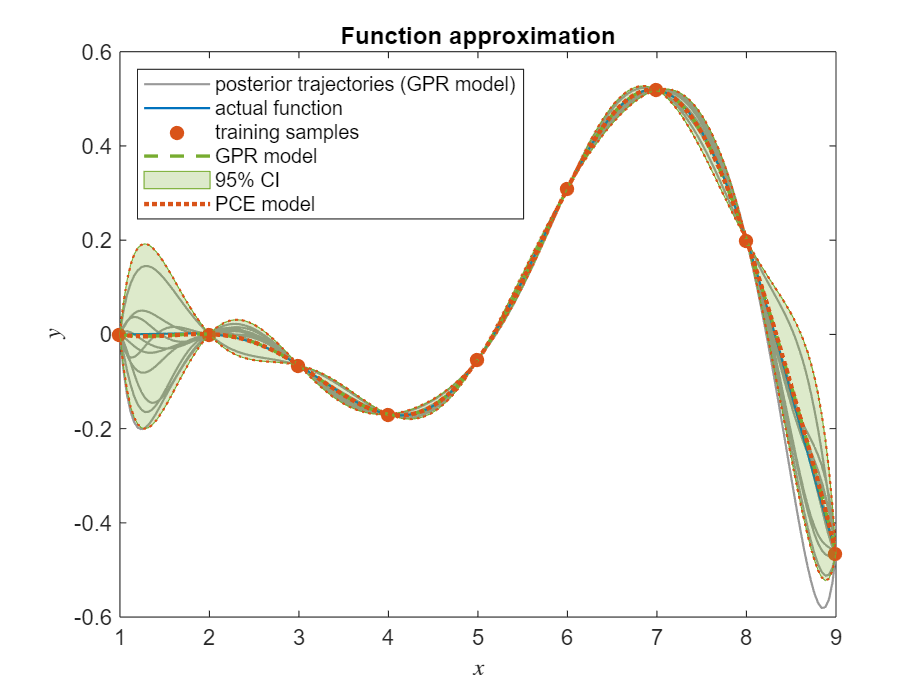

% evaluate PCE model
[~,y_pred_pce,~,cov_pred_pce] = predict_pce_gpr(M_pce_gpr,x);

% confidence interval
ci_pred_pce(:,1) = y_pred_pce - 2*sqrt(diag(cov_pred_pce));
ci_pred_pce(:,2) = y_pred_pce + 2*sqrt(diag(cov_pred_pce));

% plot
figure(1)
plot(x,y_pred_pce,':','Color',RED,'LineWidth',2,'DisplayName','PCE model');
hP = plot(x,ci_pred_pce,':','Color',RED,'LineWidth',1,'DisplayName','PCE');

hP(1).Annotation.LegendInformation.IconDisplayStyle = 'off'; % do not display in legend
hP(2).Annotation.LegendInformation.IconDisplayStyle = 'off';

The prediction method returns also the covariance between the predictions of the PCE model. This is also an approximation of the covariance of GPR predictions. The predictions at two points $x^*_i$ and $x^*_j$ read


$$y^*_i=\sum_{k=1}^Kc_k\psi_k(x^*_i)=\sum_{k=1}^Kc_k\Psi^*_{ki}$$


and


$$y^*_j=\sum_{k=1}^Kc_k\psi_k(x^*_j)=\sum_{k=1}^Kc_k\Psi^*_{kj}$$


where $\Psi^*_{ki}=\psi_k(x^*_i)$ and $\Psi^*_{kj}=\psi_k(x^*_j)$. It should be noted that, for a given pair of points $x^*_i,x^*_j$, the coefficients $\Psi^*_{ki}$ and $\Psi^*_{kj}$ are *deterministic*, whereas the posterior random variables (in Bayesian terms) are the coefficients $c_k$. Hence, $y^*_i$ and $y^*_j$ are in fact two linear combinations of the *same* Gaussian random variables $c_k$. Therefore, their covariance can be computed using the generalization of Bienaymé's identity as


$$\mathrm{cov}(y^*_i,y^*_j)=\sum_{k,n=1}^K\Psi^*_{ki}\left[\mathbf{\Sigma}_\mathbf{c}\right]_{kn}\Psi^*_{nj}$$


based on covariance matrix of the PCE coefficients $\mathbf{\Sigma}_\mathbf{c}$.

## Statistics

The PCE model readily allows computing the mean value $\mu_y$ and the variance $\sigma_y^2$ of $y$ as


$$\mu_y=c_1$$


and


$$\sigma_y^2=\sum_{k=2}^Kc_k^2$$


respectively. Since the PCE-GPR model provides PCE coefficients as random variables, we can evaluate the above two moments probabilistically. The method `get_pce_gpr_stats` carries out the calculation analytically. However, let us first proceed numerically, as follows:

- We generate a large number (`Ntraj`) of posterior samples ("trajectories") of the PCE coefficients

- We evaluate the corresponding samples of $\mu_y$ and $\sigma_y^2$

- From the samples of $\mu_y$ and $\sigma_y^2$, which we compute their expectation, variance, and distribution.

% number of coefficients
K = size(kvec,1);

% draw random PCE coefficients
pce_post = M_pce_gpr.pce_coeff + sqrtm(M_pce_gpr.cov_pce_coeff+nugget*eye(K))*randn(K,Ntraj);

% mean (= first PCE coefficient)
mu_y = pce_post(1,:);

% expectation and variance of the mean (numerical)
mean_mu_y_num = mean(mu_y);
var_mu_y_num = var(mu_y);

% distribution of the mean (numerical)
[pdf_mu_y_num,xi_mu_y] = ksdensity(mu_y);

% variance (= sum of squared PCE coefficients except the first)
sig2_y = sum(pce_post(2:end,:).^2);

% expectation and variance of the variance (numerical)
mean_sig2_y_num = mean(sig2_y);
var_sig2_y_num = var(sig2_y);

% distribution of the variance (numerical)
[pdf_sig2_y_num,xi_sig2_y] = ksdensity(sig2_y);

% plots
figure(2)
subplot(1,2,1)
plot(xi_mu_y,pdf_mu_y_num,'-','Color',BLUE,'LineWidth',1,'DisplayName','numerical'); hold on;
xlabel('$\mu_y$','interpreter','latex');
title('Posterior pdf of \mu_y');

subplot(1,2,2)
plot(xi_sig2_y,pdf_sig2_y_num,'-','Color',BLUE,'LineWidth',1,'DisplayName','numerical'); hold on;
xlabel('$\sigma_y^2$','interpreter','latex');
title('Posterior pdf of \sigma_y^2');

legend('Location','northeast');

We now compare the obtained results with the analytical predictions from the PCE-GPR method.

% retrieve statistics from PCE-GPR model
[mean_mu_y,mean_sig2_y,~,var_mu_y,var_sig2_y,~,pdf_mu_y,pdf_sig2_y] = get_pce_gpr_stats(M_pce_gpr);

% compare numerical vs analytical expectation and variance
disp(['Numerical expectation of mu_y:' num2str(mean_mu_y_num)]);

Numerical expectation of mu_y:0.071316


disp(['Analytical expectation of mu_y:' num2str(mean_mu_y)]);

Analytical expectation of mu_y:0.071359


disp(['Numerical expectation of sig2_y:' num2str(mean_sig2_y_num)]);

Numerical expectation of sig2_y:0.057432


disp(['Analytical expectation of sig2_y:' num2str(mean_sig2_y)]);

Analytical expectation of sig2_y:0.057442


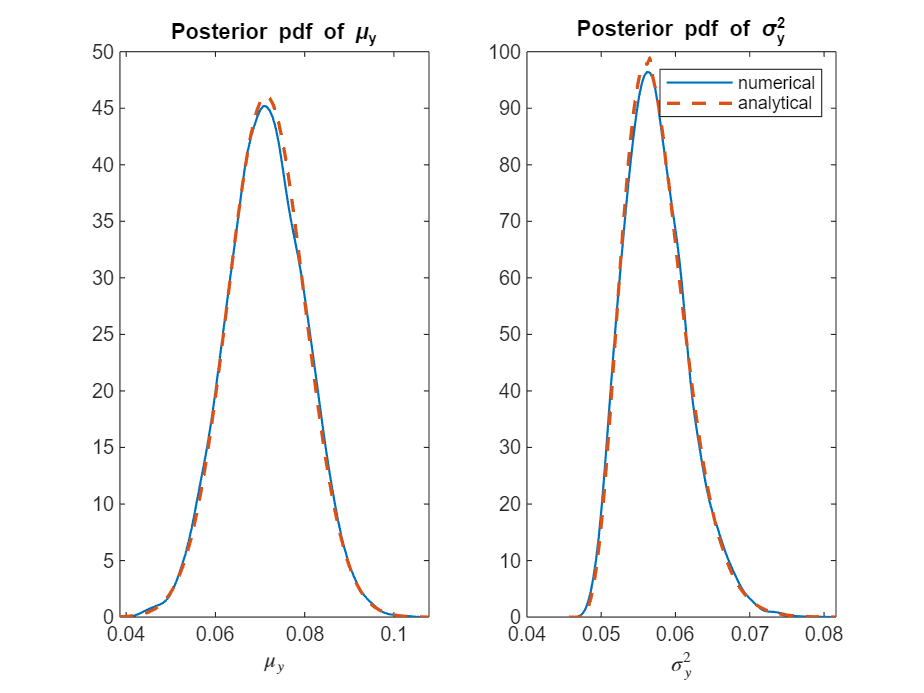


% compare numerical vs analytical posterior distribution
figure(2)
subplot(1,2,1)
plot(xi_mu_y,pdf_mu_y.pdf(xi_mu_y),'--','Color',RED,'LineWidth',1.5,'DisplayName','analytical');

subplot(1,2,2)
plot(xi_sig2_y,pdf_sig2_y.pdf(xi_sig2_y),'--','Color',RED,'LineWidth',1.5,'DisplayName','analytical');

## Hyperparameter sweep

So far, we tuned the kernel hyperparameters $\rho$, and possibly the noise ratio $\tau$, via either ML or CV, which are the two most common strategies in GPR settings. Since in this case we are dealing with an analytical 1D function, we can easily and more rigorously assess the impact of $\rho$ by sweeping its value within a given interval and evaluating the resulting error on a large number of test (Monte Carlo) samples. For the sake of visualization, we restrict the analysis of this section to a noiseless interpolation, so that $\tau=0$ and we only have the hyperparameter $\rho$ to sweep. The location of the minimum error identifies the ideal hyperparameter value.

With the PCE-GPR toolbox, the value of $\rho$ can be fixed by setting the UQLab-specific options as follows:

- Set the desired hyperparameter value as the initial value for the optimization problem (with `UQLabOpts.Optim.InitialValue`);

- Set the optimization method (`UQLabOpts.Optim.Method`) to `'none'` (= no optimization).

However, a large set of test samples is usually unavailable, and the ML or the CV error are the two most commonly used proxies for the testing error.

The ML estimation seeks to maximize the likelihood function or, typically, to minimize the negative log-likelihood function. The negative of the log-likelihood function is defined as


$$-\ln\mathcal{L}(\rho)=\frac{1}{2}\left[\ln(\det\mathbf{R})+N_\mathrm{train}\,\ln(2\pi\sigma^2)+N_\mathrm{train}\right]$$


where $\sigma^2$ is the ML estimate of the kernel variance, which reads


$$\sigma^2=\frac{1}{N_\mathrm{train}}\mathbf{y}^T\mathbf{R}^{-1}\mathbf{y}$$


The alternative is to minimize the leave-one-out (LOO) CV error. The training data are divided into a number of folds that is equal to the number of training samples. In each fold, one sample is left out from the training, and the trained model is used to predict the error for the left-out sample. The LOO-CV error that is minimized is the sum of all quadratic errors, i.e.


$$\epsilon_\mathrm{CV}\propto\sum_{l=1}^{N_\mathrm{train}}\left(y_l-\mathcal{M}_{-l}(x_l)\right)^2$$


where we denoted with $\mathcal{M}_{-l}$ the the model trained without the $l$-th training sample that we use to predict the output at the training sample itself. The LOO error is available in the properties of the UQLab model output (`.model.Error.LOO`). It is possible to specify a different number of samples to leave out in the CV scheme using the field `.CV.LeaveKOut` of the UQLab-specific options.

By deafult, the toolbox uses a hybrid covariance matrix adaptation-evolution strategy (HCMAES) optimization method to solve the associated minimization problem. A different method can be specified via the fields `.Optim.Method`.

% force interpolation mode
Noise = false;

% generate reference Monte Carlo samples
x_mc = Xdist.icdf(lhsdesign(Nmc,d));
y_mc = fun(x_mc);

% define hyperparameter sweep
rho_sweep = linspace(0,1,Nrho);
rho_sweep = rho_sweep(2:end-1); % remove extrema for which the kernel is singular
Nrho = length(rho_sweep); % update value of Nrho

% set hyperparameter optimizer to 'none' (= do not optimize)
UQLabOpts.Optim.Method = 'none';

% sweep
rmse_sweep = zeros(length(Nrho),1);
cv_sweep = zeros(length(Nrho),1);
ml_sweep = zeros(length(Nrho),1);
hbar = waitbar(0,'Hyperparameter sweep...');
for ii = 1:Nrho
    % set hyperparameter to fixed value
    UQLabOpts.Optim.InitialValue = rho_sweep(ii);

    % train
    M_pce_gpr = train_pce_gpr(x_train,y_train,distr,'UQLabOpts',UQLabOpts);
    
    % predict
    y_pred = predict_pce_gpr(M_pce_gpr,x_mc);

    % calculate RMSE
    rmse_sweep(ii) = rmse(y_pred,y_mc);

    % extract LOO-CV error
    cv_sweep(ii) = M_pce_gpr.model.Error.LOO;

    % compute ML function
    R = M_pce_gpr.kernel(M_pce_gpr.x_train,M_pce_gpr.x_train); % correlation matrix
    sig2 = 1/Ntrain*y_train'*(R\y_train); % ML variance
    ml_sweep(ii) = 1/2*(log(det(R)) + Ntrain*log(2*pi*sig2) + Ntrain);

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\EMC Group\tools\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information

---   Calculating the Kriging metamodel...                              ---
---   Calculation finished!                                             ---
Copyright 2013-2022, Stefano Marelli an


    waitbar(ii/Nrho,hbar);
end
close(hbar);

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\EMC Group\tools\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information

---   Calculating the Kriging metamodel...                              ---

                          Median        Current pop   Stall
Generation   f-count      f(x)          best f(x)     


% ML estimation
M_pce_gpr = train_pce_gpr(x_train,y_train,distr,'EstimationMethod','ML','Noise',Noise);
rho_ml = M_pce_gpr.rho;

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\EMC Group\tools\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information

---   Calculating the Kriging metamodel...                              ---

                          Median        Current pop   Stall
Generation   f-count      f(x)          best f(x)     

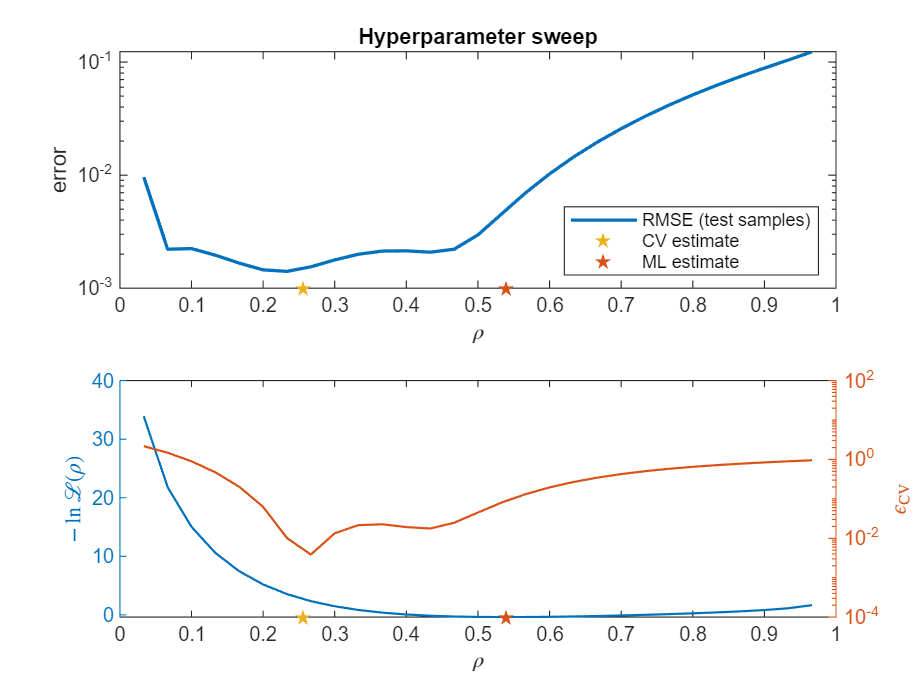


% CV estimation
M_pce_gpr = train_pce_gpr(x_train,y_train,distr,'EstimationMethod','CV','Noise',Noise);
rho_cv = M_pce_gpr.rho;

% plot
figure(3)
subplot(2,1,1)
semilogy(rho_sweep,rmse_sweep,'-','LineWidth',1.5,'DisplayName','RMSE (test samples)'); hold on;
YL = get(gca,'YLim');
semilogy(rho_cv,YL(1),'pentagram','Color',YELLOW,'MarkerFaceColor',YELLOW,'DisplayName','CV estimate');
semilogy(rho_ml,YL(1),'pentagram','Color',RED,'MarkerFaceColor',RED,'DisplayName','ML estimate');
xlabel('$\rho$','interpreter','latex');
ylabel('error')
title('Hyperparameter sweep');
legend('location','southeast');

subplot(2,1,2)
yyaxis left;
plot(rho_sweep,ml_sweep,'-','LineWidth',1,'DisplayName','Negative log-likelihood'); hold on;
YL = get(gca,'YLim');
plot(rho_ml,YL(1),'pentagram','Color',RED,'MarkerFaceColor',RED,'DisplayName','ML estimate');
xlabel('$\rho$','interpreter','latex');
ylabel('$-\ln\mathcal{L}(\rho)$','interpreter','latex');

yyaxis right;
plot(rho_sweep,cv_sweep,'-','LineWidth',1,'DisplayName','LOO-CV error'); hold on;
set(gca,'YScale','log');

YL = get(gca,'YLim');
plot(rho_cv,YL(1),'pentagram','Color',YELLOW,'MarkerFaceColor',YELLOW,'DisplayName','CV estimate');
ylabel('$\epsilon_\mathrm{CV}$','interpreter','latex');